# Speaker Recognition Using x-vectors

Speaker recognition answers the question "Who is speaking?". Speaker recognition is usually divided into two tasks: *speaker identification* and *speaker verification*. In speaker identification, a speaker is recognized by comparing their speech to a closed set of templates. In speaker verification, a speaker is recognized by comparing the likelihood that the speech belongs to a particular speaker against a predetermined threshold. Traditional machine learning methods perform well at these tasks in ideal conditions. For examples of speaker identification using traditional machine learning methods, see [Speaker Identification Using Pitch and MFCC](docid:audio_ug#mw_80e6ca1b-df6e-4ace-a3c0-109037e0eb5d) and [Speaker Verification Using i-Vectors](docid:audio_ug#mw_3aa52363-ade8-4f6a-892c-f1a45d92ddac). Audio Toolbox™ provides [`ivectorSystem`](docid:audio_ref#mw_16f16947-a396-480e-9953-1f91c81885f0) which encapsulates the ability to train an i-vector system, enroll speakers or other audio labels, evaluate the system for a decision threshold, and identify or verify speakers or other audio labels. 

In adverse conditions, the deep learning approach of x-vectors has been shown to achieve state-of-the-art results for many scenarios and applications [1]. The x-vector system is an evolution of i-vectors originally developed for the task of speaker verification.

In this example, you develop an x-vector system. First, you train a time-delay neural network (TDNN) to perform speaker identification. Then you train the traditional backends for an x-vector-based speaker verification system: an LDA projection matrix and a PLDA model. You then perform speaker verification using the TDNN and the backend dimensionality reduction and scoring. The x-vector system backend, or classifier, is the same as developed for i-vector systems. For details on the backend, see [Speaker Verification Using i-Vectors](docid:audio_ug#mw_3aa52363-ade8-4f6a-892c-f1a45d92ddac) and [`ivectorSystem`](docid:audio_ref#mw_16f16947-a396-480e-9953-1f91c81885f0).

In [Speaker Diarization Using x-vectors](docid:audio_ug#mw_5a1cde3c-5ccd-46d1-8953-26fdaaf71002), you use the x-vector system trained in this example to perform speaker diarization. Speaker diarization answers the question, "Who spoke when?".

## Download and Prepare Data

This example uses a subset of the LibriSpeech Dataset [2]. The LibriSpeech Dataset is a large corpus of read English speech sampled at 16 kHz. The data is derived from audiobooks read from the LibriVox project. Download the 100-hour subset of the LibriSpeech training data, the clean development set, and the clean test set.

tic
% dataFolder = tempdir;
% 
% datasetTrain = fullfile(dataFolder,"LibriSpeech","train-clean-100");
% if ~datasetExists(datasetTrain)
%     filename = "train-clean-100.tar.gz";
% 	url = "http://www.openSLR.org/resources/12/" + filename;
%     gunzip(url,dataFolder);
%     unzippedFile = fullfile(dataFolder,filename);
%     untar(unzippedFile{1}(1:end-3),dataFolder);
% end
% 
% datasetDev = fullfile(dataFolder,"LibriSpeech","dev-clean");
% if ~datasetExists(datasetDev)
%     filename = "dev-clean.tar.gz";
% 	url = "http://www.openSLR.org/resources/12/" + filename;
%     gunzip(url,dataFolder);
%     unzippedFile = fullfile(dataFolder,filename);
%     untar(unzippedFile{1}(1:end-3),dataFolder);
% end
% 
% datasetTest = fullfile(dataFolder,"LibriSpeech","test-clean");
% if ~datasetExists(datasetTest)
%     filename = "test-clean.tar.gz";
% 	url = "http://www.openSLR.org/resources/12/" + filename;
%     gunzip(url,dataFolder);
%     unzippedFile = fullfile(dataFolder,filename);
%     untar(unzippedFile{1}(1:end-3),dataFolder);
% end

websave('statisticsPooling1dLayer.m','https://raw.githubusercontent.com/sp-au-mu-nl/SpeechComm/refs/heads/main/MATLAB/lib/statisticsPooling1dLayer.m');

if ~exist('data/chap10', 'dir')
    gunzip('http://www.slp.k.hosei.ac.jp/~itou/book/2025/SpeechComm/data/CV19SPWav.tgz','data')
    untar('data/CV19SPWav', 'data/chap10/')
end

%dataFolder = "/Users/slp/pCloud Drive/crest/CV/common_voice_19_0/SP/";
dataFolder = "data/chap10/SP/";
datasetTrain = fullfile(dataFolder,"train");
datasetDev = fullfile(dataFolder,"dev");
datasetTest = fullfile(dataFolder,"test");

datasetTest = "data/chap10/SP/test"

Create [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) objects that point to the data. The speaker labels are encoded in the file names. Split the datastore into train, validation, and test sets. You will use these sets to train, validate, and test a TDNN.

%adsTrain = audioDatastore(datasetTrain,IncludeSubfolders=true);
tblTrain = readtable(dataFolder + "train/" + "metadata.csv");
tblTrain = sortrows(tblTrain,2);
trainLabels = categorical(tblTrain{:,13});
[~,fileNamesTrain,~] = fileparts(tblTrain{:,2});
fileNamesTrain = cellfun(@(x) [x '.wav'], fileNamesTrain, 'UniformOutput',false);
fullPathsTrain = fullfile(datasetTrain, 'wav', fileNamesTrain);
adsTrain = audioDatastore(fullPathsTrain);

%adsDev = audioDatastore(datasetDev,IncludeSubfolders=true);
tblDev = readtable(dataFolder + "dev/" + "metadata.csv");
tblDev = sortrows(tblDev,2);
devLabels = categorical(tblDev{:,13});
[~,fileNamesDev,~] = fileparts(tblDev{:,2});
fileNamesDev = cellfun(@(x) [x '.wav'], fileNamesDev, 'UniformOutput',false);
fullPathsDev = fullfile(datasetDev, 'wav', fileNamesDev);
adsDev = audioDatastore(fullPathsDev);

%adsEvaluate = audioDatastore(datasetTest,IncludeSubfolders=true);
tblEval = readtable(dataFolder + "test/" + "metadata.csv");
tblEval = sortrows(tblEval,2);
evalLabels = categorical(tblEval{:,13});
[~,fileNamesEval,~] = fileparts(tblEval{:,2});
fileNamesEval = cellfun(@(x) [x '.wav'], fileNamesEval, 'UniformOutput',false);
fullPathsEval = fullfile(datasetTest, 'wav', fileNamesEval);
adsEvaluate = audioDatastore(fullPathsEval);

Separate the datastore objects into five sets:

- `adsTrain` - Contains training set for the TDNN and backend classifier.

- `adsValidation` - Contains validation set to evaluate TDNN training progress.

- `adsTest` - Contains test set to evaluate the TDNN performance for speaker identification.

- `adsEnroll` - Contains enrollment set to evaluate the detection error tradeoff of the x-vector system for speaker verification.

- `adsDET` - Contains evaluation set used to determine the detection error tradeoff of the x-vector system for speaker verification.

indices = splitlabels(trainLabels,[0.8,0.1,0.1],"randomized");
adsValidation = subset(adsTrain,indices{2});
labelsValidation = trainLabels(indices{2});
adsTest = subset(adsTrain,indices{3});
labelsTest = trainLabels(indices{3});
adsTrain = subset(adsTrain,indices{1});
labelsTrain = trainLabels(indices{1});

% evalLabels : categorical (length = number of eval samples)
% adsEvaluate.Files の順と揃っている前提

classes = categories(evalLabels);
rng("default");   % 再現性のため

idxEnroll = [];
idxDET = [];

for i = 1:numel(classes)
    speaker = classes{i};

    % この話者のインデックスを全部取得
    idxSpeaker = find(evalLabels == speaker);

    % ランダムに 3 サンプル選ぶ（Python と同等）
    if numel(idxSpeaker) >= 3
        enrollIdx = randsample(idxSpeaker,3);
    else
        enrollIdx = idxSpeaker;  % 話者に3つ未満しかない場合
    end

    % 残りは DET 側に回す
    detIdx = setdiff(idxSpeaker, enrollIdx);

    idxEnroll = [idxEnroll; enrollIdx(:)];
    idxDET = [idxDET; detIdx(:)];
end

% Enrollment 用 audioDatastore / labels
adsEnroll = subset(adsEvaluate, idxEnroll);
labelsEnroll = evalLabels(idxEnroll);

% DET 用 audioDatastore / labels
adsDET = subset(adsEvaluate, idxDET);
labelsDET = evalLabels(idxDET);


%indices = splitlabels(evalLabels,3,"randomized"); % 各話者3つずつ))
%adsEnroll = subset(adsEvaluate,indices{1});
%labelsEnroll = evalLabels(indices{1});
%adsLeftover = subset(adsEvaluate,indices{2});
%
%adsDET = audioDatastore([adsLeftover.Files;adsDev.Files]);
%labelsDET = [evalLabels(indices{2}); devLabels];

You can reduce the training and detection error tradeoff datasets used in this example to speed up the runtime at the cost of performance. In general, reducing the data set is a good practice for development and debugging.

speedupExample = false;
if speedupExample
    idxs = splitlabels(labelsTrain,5);
    adsTrain = subset(adsTrain,idxs{1});
    labelsTrain = labelsTrain(idxs{1});

    idxs = splitlabels(labelsValidation,2);
    adsValidation = subset(adsValidation,idxs{1});
    labelsValidation = labelsValidation(idxs{1});

    idxs = splitlabels(labelsDET,5);
    adsDET = subset(adsDET,idxs{1});
    labelsDET = labelsDET(idxs{1});
end

## Input Pipeline

Create an [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) object to extract 30 MFCCs from 30 ms Hann windows with a 10 ms hop. The sample rate of the data set is 16 kHz.

fs = 16e3;
%fs = 32e3;
%fs = 48e3;
windowDuration = 0.03;
hopDuration = 0.01;
windowSamples = round(windowDuration*fs);
hopSamples = round(hopDuration*fs);
overlapSamples = windowSamples - hopSamples;
numCoeffs = 30; % 30
afe = audioFeatureExtractor( ...
    SampleRate=fs, ...
    Window=hann(windowSamples,"periodic"), ...
    OverlapLength=overlapSamples, ...
    mfcc=true);
setExtractorParameters(afe,"mfcc",NumCoeffs=numCoeffs)

Create a transform datastore that applies preprocessing to the audio and outputs features. The supporting function, xVectorPreprocess, performs speech detection and extracts features from regions of speech. When the parameter `Segment` is set to `false`, the detected regions of speech are concatenated together.

adsTrainTransform = transform(adsTrain,@(x)xVectorPreprocess(x,afe,Segment=false,MinimumDuration=0.5));

Extract all features from the training set.

features = readall(adsTrainTransform, ...
    UseParallel=canUseParallelPool);

'Processes' プロファイルを使用して並列プール (parpool) を起動中...
クラッシュ ダンプ ファイルを含んでいるため、ID: 3 を付けてジョブを保存しています。
'delete(myCluster.Jobs)' を使用すると、プロファイル Processes を指定して作成したすべてのジョブを削除することができます。'myCluster' を作成するには、'myCluster = parcluster('Processes')' を使用します。
16 個のワーカーをもつ並列プールに接続されています。


Concatenate the features and then save the global mean and standard deviation in a struct. You will use these factors to normalize features.

features = cat(1,features{:});
[S,M] = std(features,0,1);
factors = struct(Mean=M,STD=S);
clear features
factors = [];

Combine the predictor datastores with the target datastores.

cdsTrain = combine(adsTrain,arrayDatastore(labelsTrain));
cdsValidation = combine(adsValidation,arrayDatastore(labelsValidation));
cdsTest = combine(adsTest,arrayDatastore(labelsTest));
cdsEnroll = combine(adsEnroll,arrayDatastore(labelsEnroll));
cdsDET = combine(adsDET,arrayDatastore(labelsDET));

Create a new transform datastore for the training set, this time specifying the normalization factors and `Segment` as `true`. Now, features are normalized by the global mean and standard deviation, and then the file-level mean. The individual speech regions detected are not concatenated. Extract all the features and corresponding targets.

adsTrainTransform = transform(cdsTrain,@(x)xVectorPreprocess(x,afe, ...
    Segment=true,Factors=factors,MinimumDuration=0.5));
xtTrain = readall(adsTrainTransform,UseParallel=canUseParallelPool);

Separate the features and targets.

xTrain = cat(1,xtTrain{:,1});
tTrain = cat(1,xtTrain{:,2});

Apply the same transformation to the validation, test, enrollment, and DET sets.

adsValidationTransform = transform(cdsValidation,@(x)xVectorPreprocess(x,afe, ...
    Segment=true,Factors=factors,MinimumDuration=0.5));
xtValidation = readall(adsValidationTransform,UseParallel=canUseParallelPool);
xValidation = cat(1,xtValidation{:,1});
tValidation = cat(1,xtValidation{:,2});

adsTestTransform = transform(cdsTest,@(x)xVectorPreprocess(x,afe, ...
    Segment=true,Factors=factors,MinimumDuration=0.5));
xtTest = readall(adsTestTransform,UseParallel=canUseParallelPool);
xTest = cat(1,xtTest{:,1});
tTest = cat(1,xtTest{:,2});

adsEnrollTransform = transform(cdsEnroll,@(x)xVectorPreprocess(x,afe, ...
    Segment=true,Factors=factors,MinimumDuration=0.5));
xtEnroll = readall(adsEnrollTransform,UseParallel=canUseParallelPool);
xEnroll = cat(1,xtEnroll{:,1});
tEnroll = cat(1,xtEnroll{:,2});

adsDETTransform = transform(cdsDET,@(x)xVectorPreprocess(x,afe, ...
    Segment=true,Factors=factors,MinimumDuration=0.5));
xtDET = readall(adsDETTransform,UseParallel=canUseParallelPool);
xDET = cat(1,xtDET{:,1});
tDET = cat(1,xtDET{:,2});

## x-vector Network

The table summarizes the architecture of the network described in [1] and implemented in this example. T is the total number of frames (feature vectors over time) in an audio signal. N is the number of classes (speakers) in the training set.

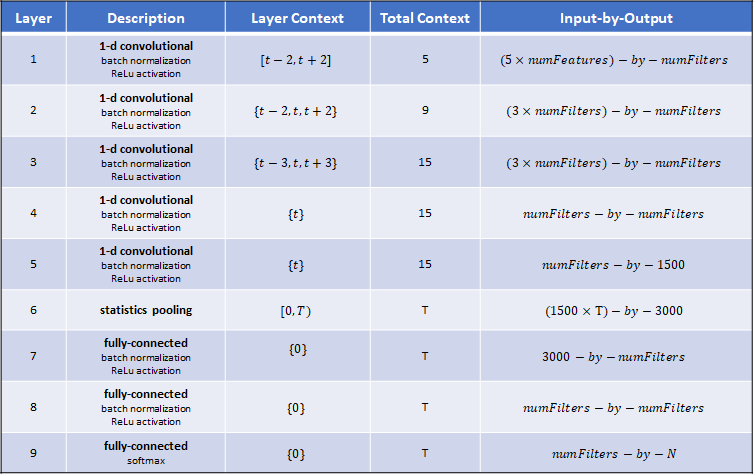

Define the network. You can change the model size by increasing or decreasing the `numFilters` parameter.

numFilters = 256; % 512
dropProb = 0.1; % 0.02; % 0.2

classes = unique(labelsTrain);
numClasses = numel(classes);

layers = [
    sequenceInputLayer(afe.FeatureVectorLength,MinLength=15,Name="input")

    convolution1dLayer(5,numFilters,DilationFactor=1,Name="conv_1")
    batchNormalizationLayer(Name="BN_1")
    dropoutLayer(dropProb,Name="drop_1")
    reluLayer(Name="act_1")

    convolution1dLayer(3,numFilters,DilationFactor=2,Name="conv_2")
    batchNormalizationLayer(Name="BN_2")
    dropoutLayer(dropProb,Name="drop_2")
    reluLayer(Name="act_2")

    %convolution1dLayer(3,numFilters,DilationFactor=3,Name="conv_3")
    %batchNormalizationLayer(Name="BN_3")
    %dropoutLayer(dropProb,Name="drop_3")
    %reluLayer(Name="act_3")

    %convolution1dLayer(1,numFilters,DilationFactor=1,Name="conv_4")
    %batchNormalizationLayer(Name="BN_4")
    %dropoutLayer(dropProb,Name="drop_4")
    %reluLayer(Name="act_4")

    convolution1dLayer(1,1500,DilationFactor=1,Name="conv_5")
    batchNormalizationLayer(Name="BN_5")
    dropoutLayer(dropProb,Name="drop_5")
    reluLayer(Name="act_5")

    statisticsPooling1dLayer(Name="statistics_pooling")

    fullyConnectedLayer(numFilters,Name="fc_1")
    batchNormalizationLayer(Name="BN_6")
    dropoutLayer(dropProb,Name="drop_6")
    reluLayer(Name="act_6")

    fullyConnectedLayer(numFilters,Name="fc_2")
    batchNormalizationLayer(Name="BN_7")
    dropoutLayer(dropProb,Name="drop_7")
    reluLayer(Name="act_7")

    fullyConnectedLayer(numClasses,Name="fc_3")
    softmaxLayer(Name="softmax")
    ];

The model requires statistical pooling which is implemented as a custom layer and placed in your current folder when you open this example. Display the contents of the custom layer.

type("statisticsPooling1dLayer.m")


classdef statisticsPooling1dLayer < nnet.layer.Layer & nnet.layer.Formattable
    % This class is only for use in this example. It may be changed or
    % removed in a future release. 

    methods
        function this = statisticsPooling1dLayer(options)
            arguments
                options.Name = ''
            end
            this.Name = options.Name;
        end
        
        function X = predict(~, X)
            X = dlarray(stripdims([mean(X,3);std(X,0,3)]),"CB");
        end
        function X = forward(~, X)
            X = X + 0.0001*rand(size(X),"single");
            X = dlarray(stripdims([mean(X,3);std(X,0,3)]),"CB");
        end
    end
    
end


## Training Options

To specify training options, use `trainingOptions`. Set the mini-batch size as appropriate for your hardware.

mbsize = 256;
options = trainingOptions("adam", ...
    OutputNetwork="best-validation", ...
    LearnRateSchedule="none", ... % piecewise %    LearnRateDropPeriod=2, ...
    initialLearnRate=1e-3, ... % 追加
    MaxEpochs=6, ... % 5
    Shuffle="every-epoch", ...
    MiniBatchSize=mbsize, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    SequenceLength="longest", ... % shortest
    ValidationData={xValidation,tValidation}, ...
    ValidationFrequency=200, ...  % 400
    DispatchInBackground=canUseParallelPool);

## Train Network

To train the network, use `trainnet`.

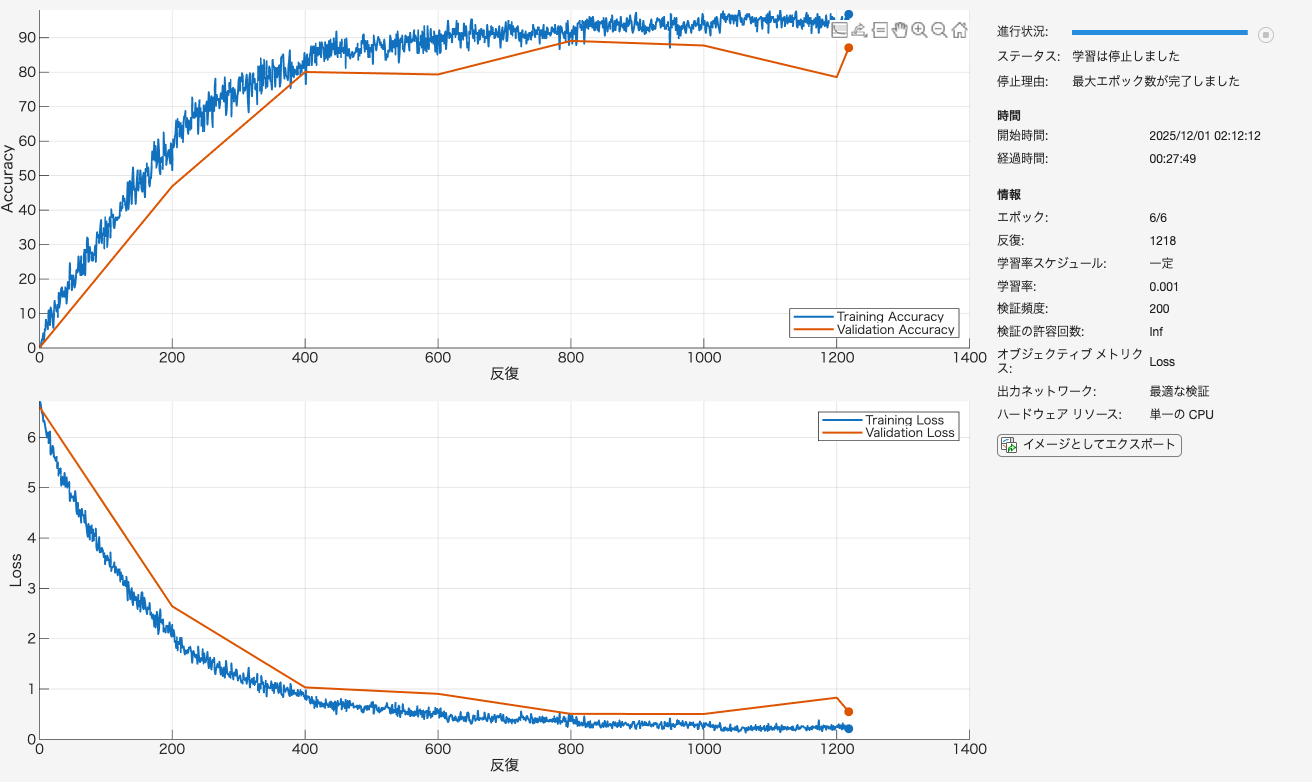

dlnet = trainnet(xTrain,tTrain,layers,"crossentropy",options);

Evaluate the TDNN speaker recognition accuracy using the held-out test set.  Decode the predictions and then compute the prediction accuracy. To speed up this example, use a large mini-batch size. If you reduce the mini-batch size to 1, the accuracy is approximately 98% because you are no longer discarding relevant data to make consistent sequence lengths.

scores = minibatchpredict(dlnet,xTest, ...%xTest is in memory
    MiniBatchSize=mbsize); %, ...
    %SequenceLength="shortest");

yTest = scores2label(scores,classes,2);

accuracy = 100*mean(tTest(:)==yTest(:))

accuracy = 87.6201

save('CV_SPKREC.mat', 'dlnet');
toc

経過時間は 1771.374648 秒です。


## References

[1] Snyder, David, et al. "x-vectors: Robust DNN Embeddings for Speaker Recognition." *2018 IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP)*, IEEE, 2018, pp. 5329–33. *DOI.org (Crossref)*, doi:10.1109/ICASSP.2018.8461375.

[2] V. Panayotov, G. Chen, D. Povey and S. Khudanpur, "Librispeech: An ASR corpus based on public domain audio books," *2015 IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP)*, Brisbane, QLD, 2015, pp. 5206-5210, doi: 10.1109/ICASSP.2015.7178964

## Supporting Functions

#### Feature Extraction and Normalization

function output = xVectorPreprocess(audioData,afe,nvargs)
% This function is only for use in this example. It may be changed or
% removed in a future release.
arguments
    audioData
    afe
    nvargs.Factors = []
    nvargs.Segment = true;
    nvargs.MinimumDuration = 1;
    nvargs.UseGPU = false;
    nvargs.SegmentDuration = 2;
end

isCombined = numel(audioData)==2;
if isCombined
    label = audioData{2};
    audioData = audioData{1};
end

% Place on GPU if requested
if nvargs.UseGPU
    audioData = gpuArray(audioData);
end

% Scale
audioData = audioData/max(abs(audioData(:)));

% Protect against NaNs
audioData(isnan(audioData)) = 0;

% Determine regions of speech
mergeDur = 0.2; % seconds
idx = detectSpeech(audioData,afe.SampleRate,MergeDistance=afe.SampleRate*mergeDur);

% If a region is less than MinimumDuration seconds, drop it.
if nvargs.Segment
    idxToRemove = (idx(:,2)-idx(:,1))<afe.SampleRate*nvargs.MinimumDuration;
    idx(idxToRemove,:) = [];
end

segLen = round(nvargs.SegmentDuration*afe.SampleRate);
idxLong = idx(:,2)-idx(:,1) > segLen;
idx(idxLong,2) = idx(idxLong,1) + segLen - 1;

% Extract features
numSegments = size(idx,1);
features = cell(numSegments,1);
for ii = 1:numSegments
    temp = single(extract(afe,audioData(idx(ii,1):idx(ii,2))));
%        SampleRateMismatchRule="resample"));
    if isempty(temp)
        temp = zeros(15,30,"single");
    end
    features{ii} = temp;
end

if ~isempty(nvargs.Factors)
    % Standardize features
    features = cellfun(@(x)(x-nvargs.Factors.Mean)./nvargs.Factors.STD,features,UniformOutput=false);

    % Cepstral mean subtraction (for channel noise)
    fileMean = mean(cat(1,features{:}),"all");
    features = cellfun(@(x)x - fileMean,features,UniformOutput=false);
end

if ~nvargs.Segment
    features = {cat(1,features{:})};
end

if isCombined
    output = {features,repelem(label,numel(features),1)};
else
    output = features;
end

end

*Copyright 2020-2023 The MathWorks, Inc.*